# Parameter estimation and identifiability, uncertainty, and sensitivity analyses for a dengue model

**Implemented model**

Human population


$$\dot{H_s} = - \beta_h \frac{M_i}{M} H_s + (H_e + H_i + H_r) \mu_h\\
\dot{H_e} = \beta_h  \frac{M_i}{M} Hs - (\theta_h + \mu_h) H_e\\
\dot{H_i} = \theta_h  H_e - (\gamma_h + \mu_h) H_i\\
\dot{H_r} = \gamma_h H_i - \mu_h H_r$$


with $H=H_s+H_e+H_i+H_r$

Mosquito population


$$\dot{M_s} = \lambda - \beta_m \frac{H_i}{H} M_s - \mu_m M_s\\
\dot{M_e} = \beta_m \frac{H_i}{H} M_s - (\theta_m + \mu_m) M_e\\
\dot{M_i} = \theta_m M_e - \mu_m M_i$$


with $M = M_S +M_e+M_i$ 

**Taken from **

Lizarralde-Bejarano DP, Rojas-Díaz D, Arboleda-Sánchez S, Puerta-Yepes ME (2020) Sensitivity, uncertainty and identifiability analyses to define a dengue transmission model with real data of an endemic municipality of Colombia. PLOS ONE 15(3): e0229668. [https://doi.org/10.1371/journal.pone.0229668](https://doi.org/10.1371/journal.pone.0229668)

**Real data**

We implemented the number of dengue cases per week reported for Itagüí, a municipality in Colombia, during the outbreak that occurred in 2010.

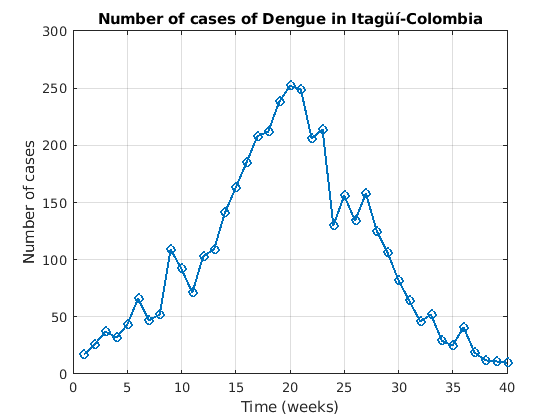

load('Itagui.mat');

ydata = Itagui(1:40)';

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

clf
plot(ydata, '-o', 'LineWidth',1.5)
title('Number of cases of Dengue in Itagüí-Colombia')
ylabel('Number of cases')
xlabel('Time (weeks)')
grid on

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)

syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

H = Hs + He + Hi + Hr;
M = Ms + Me + Mi;

ode1 = diff(Ms) == lambda - beta_m * Hi * Ms/H - mu_m * Ms;
ode2 = diff(Me) == beta_m * Hi * Ms/H - (theta_m + mu_m) * Me;
ode3 = diff(Mi) == theta_m * Me - mu_m * Mi;
ode4 = diff(Hs) == - beta_h * Mi * Hs/M + (He + Hi + Hr) * mu_h;
ode5 = diff(He) == beta_h * Mi * Hs/M - (theta_h + mu_h) * He;
ode6 = diff(Hi) == theta_h * He - (gamma_h + mu_h) * Hi;
ode7 = diff(Hr) == gamma_h * Hi - mu_h * Hr;
ode8 = diff(Hit) == theta_h * He;

odes = [ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars = [Hit Hi Me Hr Hs He Ms Mi];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [17 17             %Hit0
          17 17             %Hi    
          0	100             %Me
          0 100             %Hr
          50000	250000      %Hs
          0	1000            %He
          0	120000          %Ms
          0	100             %Mi
         ];
     
Range2 = [0	4           %beta_h
          0	4           %beta_m
          0.4	1.8     %gamma_h
          0	42694       %Lambda
          0.0004 0.0004 %mu_h
          0.01 0.6      %mu_m   
          0.7	1.75    %theta_h
          0.58	0.88    %tetha_m
        ];     

Range = [Range1; Range2];

ParNames = {'\lambda'; '\beta_m'; '\mu_m'; '\theta_m'; '\beta_h'; '\theta_h'; '\gamma_h'};
VarNames = {'M_e(0)'; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)'};

FullNames = [VarNames;ParNames];

Finally, use the gsua_dpmat to create the functional table

[T,~] = gsua_dpmat(odes,vars,[0 D-1],'Model','output',2,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Row = ["M_e(0)"; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)';...
         '\beta_h';'\beta_m'; '\gamma_h';'\Lambda'; '\mu_m'; '\theta_h'; '\theta_m'];

**Parameter estimation**

First, define the optimization process options: *Solver, maximum function evaluation, maximum iterations per estimation*, among others.

Solver = 'fmincon';    
Opt = optimoptions('fmincon','UseParallel', false,'MaxFunctionEvaluations',30000, ...
    'MaxIterations', 3000, 'Display','off');

Define the number of parameter estimations to perform and define the vectors to save the estimated parameters and their respective cost value, i.e., residual.

N = 5000;
Residual = zeros(N,1);
Params = zeros(N,13);

parfor i = 1:N
    [T_est, ResTemp] = gsua_pe(T,xdata, ydata,'solver',Solver,'N',1,'opt',Opt,'save',false);
    Residual(i) = ResTemp;
    Params(i,:) = T_est.Estfmincon;
end

Sort each set of parameters according to each residual value

[ResidualSorted, idx] = sort(Residual);
EstimatedParams = Params(idx, :);

save("Results/Estimations/Estimations_Itagui4.mat", "EstimatedParams", "ResidualSorted")

**Load the estimated factors and sorted by residual value**

addpath('Results')
EstimatedParamsFinal = [];
ResidualFinal = [];

for i = 1:4
    load("Results/Estimations/Estimations_Itagui" + num2str(i) + ".mat");
    EstimatedParamsFinal = [EstimatedParams; EstimatedParamsFinal];
    ResidualFinal = [ResidualSorted; ResidualFinal];
end

[~, idx] = sort(ResidualFinal);
EstimatedParams = EstimatedParamsFinal(idx, :);

**Simulate some factor estimations**

We selected 4000-factor estimations to simulate. Those curves follow the trend of real data, the remaining 2000 present aberrant behavior.

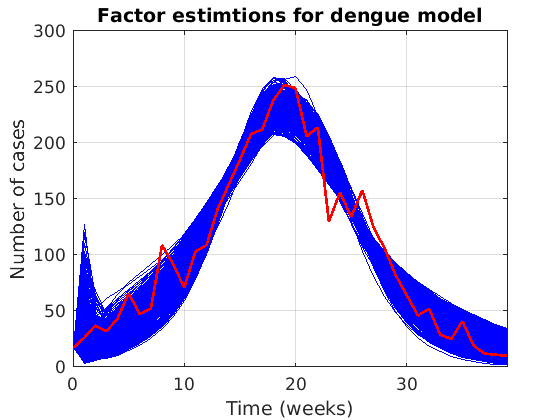

N = 4000;
ysim = zeros(length(xdata), N);

for i = 1 : N
    ysim(:, i) = gsua_deval(EstimatedParams(i,:), T, xdata);
end

close all
figure
plot(xdata, ysim, 'b')
hold on
plot(xdata, ydata, 'r','Linewidth', 2)
title('Factor estimtions for dengue model')
xlabel('Time (weeks)', 'FontSize', 13)
ylabel('Number of cases', 'FontSize', 13)
xlim([0 39])
set(gca,'FontSize',13)
grid on 

**Best factor estimation curve**

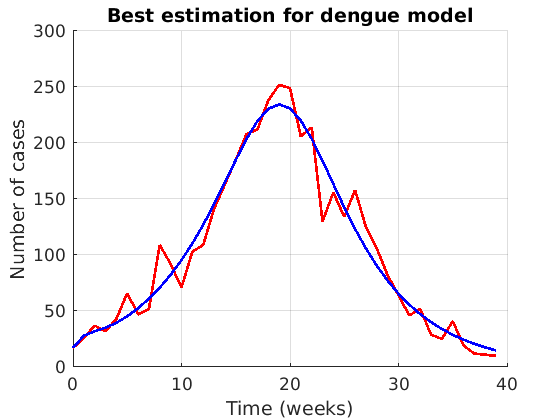

Best = ysim(:, 1);
BestParams = EstimatedParams(1,:);
save("Results/Estimations/Best_Itagui.mat", "BestParams","Best")

close all
figure
hold on
plot(xdata, ydata, 'r','Linewidth', 2)
plot(xdata, Best, 'b','Linewidth', 2)
title('Best estimation for dengue model')
xlabel('Time (weeks)', 'FontSize', 13)
ylabel('Number of cases', 'FontSize', 13)
set(gca,'FontSize',13)
grid on 

**Identifiability analysis for 4000-factor estimations**

Using the gsua_ia we obtain a table with: a nominal value of each factor as the median of the estimations, the parametric CI using the following equation:


$$  X_i \in \left[\text{med}(X_i) \pm 1.96 \sqrt{\frac{\pi}{2n}}\hat{\sigma}_{i}\right]$$


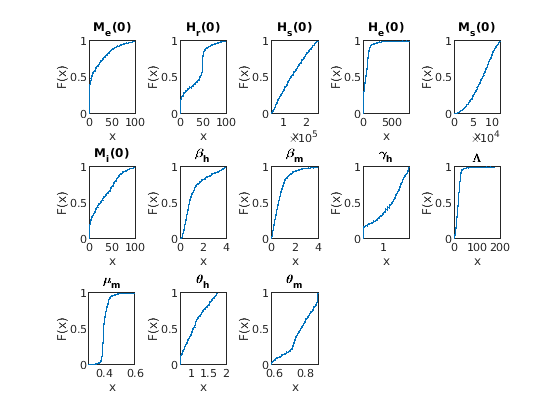

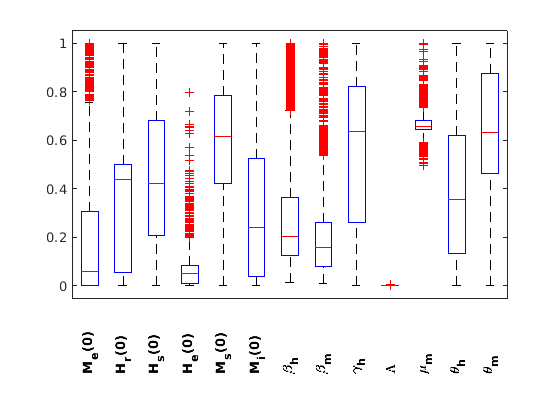

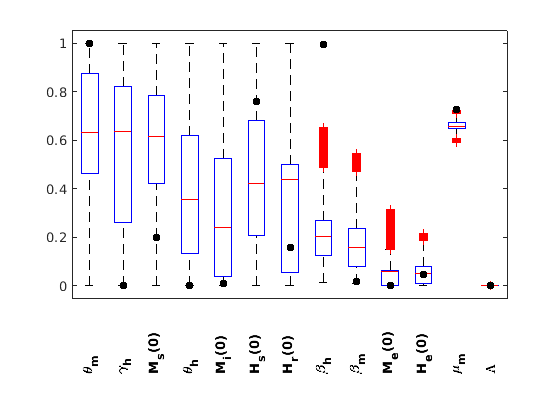

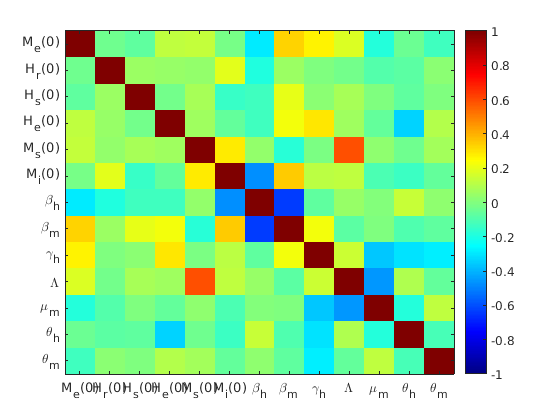

T = 13×4 table
                         Range               Nominal            Est           index  
                ________________________    __________    _______________    ________

    M_e(0)          4.8339        6.7131        5.7735    [1×4000 double]    0.082618
    H_r(0)          42.951        44.867        43.909    [1×4000 double]    0.063746
    H_s(0)      1.3224e+05    1.3657e+05    1.3441e+05    [1×4000 double]    0.065882
    H_e(0)          47.278        52.662         49.97    [1×4000 double]    0.070089
    M_s(0)           72885         75110         73998    [1×4000 double]    0.096164
    M_i(0)          22.866        25.001        23.934    [1×4000 double]     0.08843
    \beta_h        0.78172       0.85723 

T_ia = gsua_ia(T, EstimatedParams(1:N,:)',false,false);

**Uncertainty analysis for parametric CI **

Progress: 100%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:9
Estimated stop time (h:m:s): 17:42:50
Number of simulations: 2000


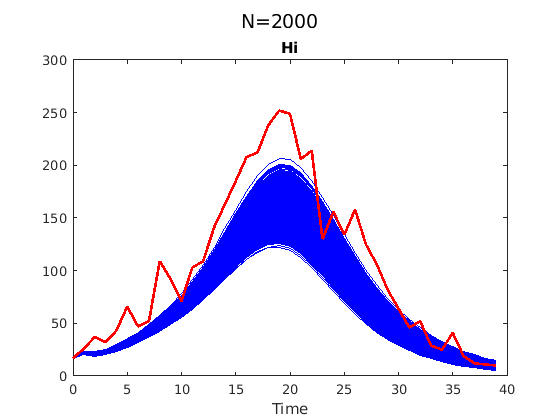

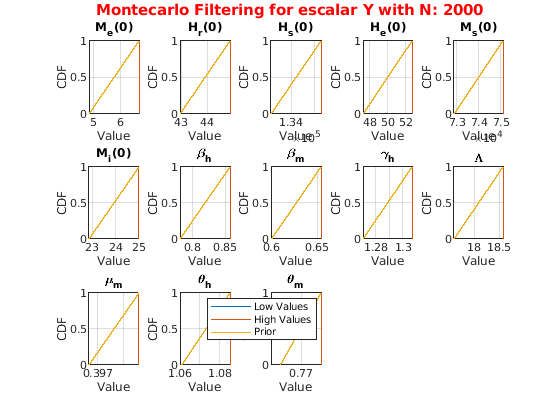

clf
N = 1000; 
M = gsua_dmatrix(T_ia,N,'Method','Sobol');
gsua_ua(M, T_ia,'xdata', xdata, 'ynom', ydata, 'parallel', false);

**Sensitivity analysis (SA): estimation intervals**

Perform the SA using the estimation intervals, i.e., the estimation box

N = 10000; 
M = gsua_dmatrix(T,N,'Method','Sobol');
T_sa = gsua_sa(M, T);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Progress: 7%
Estimated processing time (h:m:s): 0:7:38
Remaining time (h:m:s): 0:7:7
Elapsed time (h:m:s): 0:0:30
Estimated stop time (h:m:s): 17:55:20
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:4:56
Remaining time (h:m:s): 0:4:17
Elapsed time (h:m:s): 0:0:39
Estimated stop time (h:m:s): 17:52:38
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:3:44
Remaining time (h:m:s): 0:2:59
Elapsed time (h:m:s): 0:0:44
Estimated stop time (h:m:s): 17:51:26
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:3:7
Remaining time (h:m:s): 0:2:17
Elapsed time (h:m:s): 0:0:50
Estimated stop time (h:m:s): 17:50:49
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:2:46
Remaining time (h:m:s): 0:1:51
Elapsed time (h:m:s): 0:0:55
Estimated stop time (h:m:s): 17:50:28

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1.0000

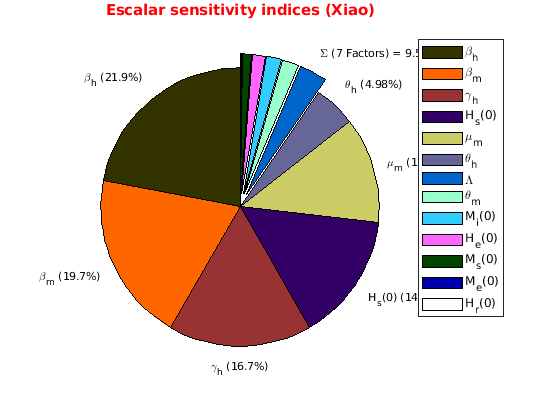

clf
gsua_plot('Pie',T_sa,T_sa.STi)

**SA: parametric confident intervals**

Perform the SA using the confident intervals using the median value of the parameters

N = 10000; 
M = gsua_dmatrix(T_ia,N,'Method','Sobol');
T_sa = gsua_sa(M, T_ia);

Progress: 7%
Estimated processing time (h:m:s): 0:1:22
Remaining time (h:m:s): 0:1:16
Elapsed time (h:m:s): 0:0:5
Estimated stop time (h:m:s): 17:57:5
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:21
Remaining time (h:m:s): 0:1:10
Elapsed time (h:m:s): 0:0:10
Estimated stop time (h:m:s): 17:57:4
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:22
Remaining time (h:m:s): 0:1:5
Elapsed time (h:m:s): 0:0:16
Estimated stop time (h:m:s): 17:57:5
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:22
Remaining time (h:m:s): 0:1:0
Elapsed time (h:m:s): 0:0:22
Estimated stop time (h:m:s): 17:57:5
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:23
Remaining time (h:m:s): 0:0:55
Elapsed time (h:m:s): 0:0:27
Estimated stop time (h:m:s): 17:57:6
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:24
Remaining time (h:m:s): 0:0:50
Elapsed

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 0.9994

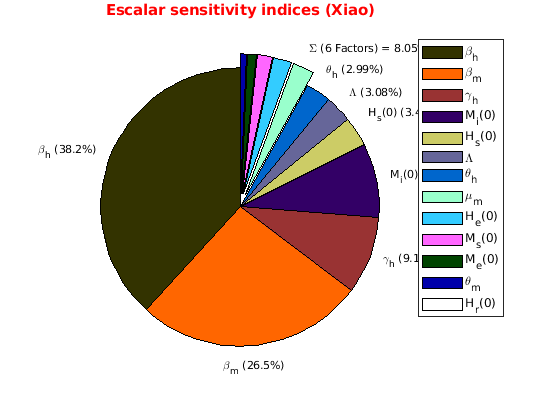

clf
gsua_plot('Pie',T_sa,T_sa.STi)